# Simulación de ec. de Langevin

Para la resolución del problema se utilizará la **ecuación de Langevin** puesto que es un módelo clásico que describe el movimiento de una párticula que se encuentra bajo la enfluencia de **fuerzas deterministas** (la fricción y los potenciales de interacción) y el **ruido estocástico** (que representa las fluctuaciones térmicas).


$$m *\frac{d^2 x_i }{{\textrm{dt}}^2 }=-\eta_i v_i -k_i x_i -k_{\textrm{ij}} \left(x_i -x_j \right)+\sqrt{\frac{2k_b T}{\eta }}$$


para cada partícula i, donde:

- $\eta_i v_i$ representa un **término de amortiguamiento** (si está presente).

- $k_i x_i$ es el término restaurador del **resorte anclado a un punto fijo**.

- $k_{\textrm{ij}} \left(x_i -x_j \right)$ representa la **fuerza entre partículas vecinas**.

- $k_b$ es la constante de Boltzman que la igualaremos a 1.

- $T$ es la temperatura.

- $\textrm{Wt}$ es un proceso de Wiener (ruido browniano).

- $\textrm{dWt}$ es su diferencial.

Reformularemos a un sistema de primer orden sabiendo que:

$\frac{{\textrm{dx}}_i }{\textrm{dt}}=v_i$;

Escribimos el sistema de siguiente manera:


$$m *\frac{dx_i }{\textrm{dt}}=-\eta_i v_i -k_i x_i -k_{\textrm{ij}} \left(x_i -x_j \right)+\sqrt{\frac{2k_b T}{\eta }}$$


Despejamos la la derivada de la velocidad dividiendo por m:


$$\frac{dx_i }{\textrm{dt}}=-\frac{\eta_i v_i }{m}-\frac{k_i x_i }{m}-\frac{k_{\textrm{ij}} \left(x_i -x_j \right)}{m}+\frac{\sqrt{\frac{2k_b T}{\eta }}}{m}$$


Para la resolución de esta ecuación es necesaria la **integral de Itô**, generalización de la **integral de Riemann** cuando hay terminos estocásticos en el sistema.


$$\textrm{dx}=\int \left(-\frac{\eta_i v_i }{m}-\frac{k_i x_i }{m}-\frac{k_{\textrm{ij}} \left(x_i -x_j \right)}{m}\right)\;\textrm{dt}+\int \frac{\sqrt{\frac{2k_b T}{\eta }}}{m}d{\mathrm{W}}_t$$


Por último, para resolver estas integrales se utilizará el **método de Euler-Maruyama **con el fin de discretizar y obtener la solución deseada. Al utilizar este método el resultado de la ecuación es la siguiente:


$$x_{n+1} =x_n +\left(-\frac{\eta_n x_n }{m}-\frac{k_i {}_1{x_n }}{m}-\frac{k_{\textrm{ij}} \left({}_1{x_n }-{{}_2x_{n+1}} \right)}{m}\right)\textrm{dt}+\frac{1}{m}\sqrt{\frac{2k_b T}{\eta }}dW_n$$



$$x_{n+1} =x_n +v_n \textrm{dt}$$


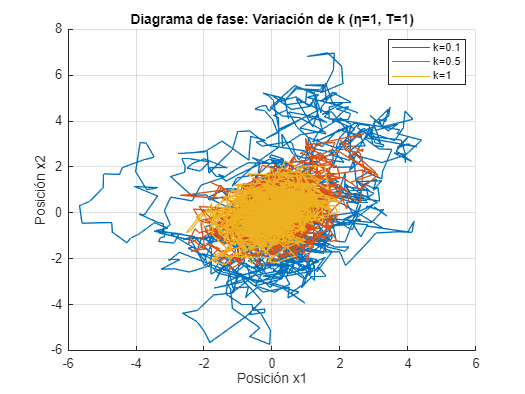

% Parámetros del sistema
m = 1;              % Masa
eta_values = [1, 5, 10];  % Valores de eta (coef. de fricción)
k_values = [0.1, 0.5, 1];  % Valores de k1        
x1_0 = 0;           % Posición inicial de la primera partícula
x2_0 = 0;           % Posición inicial de la segunda partícula
tspan = [0, 100];      % Tiempo total de simulación
dt = 0.1;            % Paso de tiempo
N = tspan(2) / dt;    % Número de pasos
t = linspace(tspan(1), tspan(2), N);  % Vector de tiempo
kb = 1;               % Constante de Boltzmann
T_values = [1, 2, 5, 7, 10];  % Valores de temperatura

% Inicialización de variables
x1 = zeros(1, N); % Posición de la primera partícula
x2 = zeros(1, N); % Posición de la segunda partícula
x1(1) = x1_0;
x2(1) = x2_0;

x1_eq = 0;
x2_eq = 0;

% Simulación para diferentes valores de k con eta = 1 y T = 1
figure;
hold on;
for k = k_values
    sqrt_term1 = sqrt((2 * kb * 1));
    sqrt_term2 = sqrt((2 * kb * 1));
    for n = 1:N-1
        dW1 = sqrt(dt) * randn;  % Incremento de Wiener
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (- 2*k * (x1(n)-x1_eq) + k*(x2(n)-x2_eq))* dt + sqrt_term1 * dW1;
        
        x2(n+1) = x2(n) +( - 2*k * (x2(n)-x2_eq) + k*(x1(n)-x1_eq))* dt + sqrt_term2 * dW2;
    end
    plot(x1, x2, 'DisplayName', ['k=' num2str(k)]);
end
xlabel('Posición x1'); ylabel('Posición x2');
title('Diagrama de fase: Variación de k (η=1, T=1)');
legend; grid on;
hold off;

Se oberva como a medida que incrementa la constante de elasticidad la posición de las párticulas varia menos que cuanto esta constante es menor, esto se debe a con mayor constante de elasticidad la rigidez aumenta y se desplazaran menos.

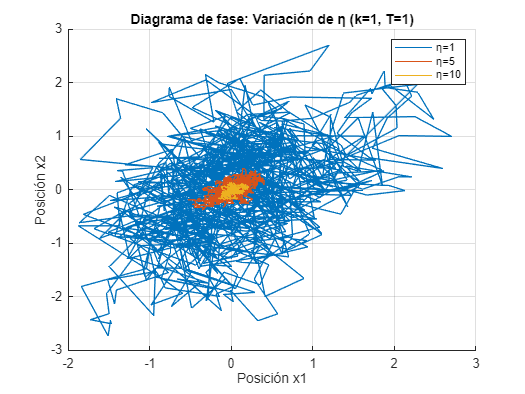

% Simulación para diferentes valores de eta con k = 1 y T = 1
figure;
hold on;
for eta = eta_values
    sqrt_term1 = sqrt((2* kb * 1) / eta);
    sqrt_term2 = sqrt((2* kb * 1) / eta);
    for n = 1:N-1
        dW1 = sqrt(dt) * randn;  % Incremento de Wiener
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (- 2*1 * (x1(n)-x1_eq) + 1*(x2(n)-x2_eq))/eta * dt + sqrt_term1/eta * dW1;
        
        x2(n+1) = x2(n) + (- 2*1 *(x2(n)-x2_eq) + 1*(x1(n)-x1_eq))/eta * dt + sqrt_term2/eta * dW2;
        
    end
    plot(x1, x2, 'DisplayName', ['η=' num2str(eta)]);
end
xlabel('Posición x1'); ylabel('Posición x2');
title('Diagrama de fase: Variación de η (k=1, T=1)');
legend; grid on;
hold off;

Se comprueba que conforme la constante de viscosidad disminuye la párticula se mueve más por el espacio. Con una viscosidad ,ayor la párticula se despaza alrededor de un espacio más pequeño.

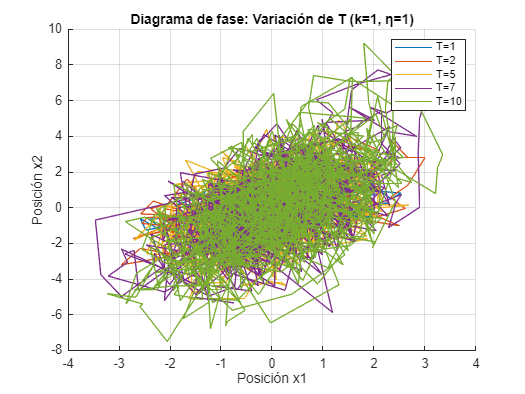

% Simulación para diferentes valores de T con k = 1 y eta = 1
figure;
hold on;
for T = T_values
    sqrt_term1 = sqrt((2 * kb * 1)/1);
    sqrt_term2 = sqrt((2 * kb * T)/1);
    for n = 1:N-1
        dW1 = sqrt(dt) * randn;
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (- 2*1 * (x1(n)-x1_eq) + 1*(x2(n)-x2_eq)) * dt + sqrt_term1 * dW1;
        
        x2(n+1) = x2(n) + (- 2*1 * (x2(n)-x2_eq) + 1*(x1(n)-x1_eq)) * dt + sqrt_term2 * dW2;
        
    end
    plot(x1, x2, 'DisplayName', ['T=' num2str(T)]);
end
xlabel('Posición x1'); ylabel('Posición x2');
title('Diagrama de fase: Variación de T (k=1, η=1)');
legend; grid on;
hold off;

A mayor temperatura las párticulas sufren mas ruido térmico, dispersandose más las trayectorias en el espacio. En cambio, para una menor temperatura las párticulas siguen unas trayectorias más suaves.